## `ME 418/518 Project: Residual-Aware RL-MPC `

## `Residual Based Q-Learning for MPC Parameters`

close all hidden; clear; clc;
rng(418);

### 1. Load Data & Models

load('data/identified_models.mat');
A = A_n4; B = B_n4; C = C_n4; 
[nx, nu] = size(B); ny = size(C,1);

% RL and Simulation Parameters

N_episodes = 100;
T_final = 400;
goal_pos = 0.45;

### 2. RL Agent Configuration

The RL agent  only observes the residual error from models as a categorical feature. Which makes the RL model spesific for dealing with themodel mismatch for MPC design. Instead of directly controlling the simulation, RL selects a parameter set based on model mismatch. Actions are as defined:

% State Space is discretized residual levels which are Low, Medium, High.
n_states = 3; 
n_actions = 3; 

% Residual Discretization Thresholds define what "Low", "Medium", "High"
% residual means. Interveal is chosen from the sample distribution of
% baseline MPC residuals.
res_bins = [0.65, 0.95]; 

% Q-Table Initialization for tabular Q Learing (3x3 table to map states and
% actions)
Q_table = zeros(n_states, n_actions);

% Hyperparameters are conventional literature values
alpha = 0.2;    % Learning Rate
gamma = 0.95;   % Discount Factor
epsilon = 0.6;  % Exploration Rate

Modes = struct();

Action 1: High-Residual Recovery = Model is failing (Residual is high). The linear model predicts the favored motion is good, but physics shows that the car is stuck in the valley. We tune the MPC to bias to recover from the ill-favored action.

Action 2: Low-Residual Tracking = When the model is accurate (Residual is low), RL basically trusts the identifiaction model's prediction. However, tunes MPC parameter Q high to aggressively track the goal.

Action 3: Conservative Hold = RL decides that the state is uncertain. Thus penalizes input usage (High R) to stabilize the current state.

% Action 1: High Residual Recovery 
Modes(1).Name = 'Recovery';
Modes(1).Q = 10; % Lowered trust to identification model
Modes(1).R = 0.01; % Ideal power for motor to overcome the recovery
Modes(1).Ref = -1.2; % Bias setpoint to the leftwards wall induce negative force

% Action 2: Low-Residual Tracking
Modes(2).Name = 'Tracking';
Modes(2).Q = 100; % Full trust to identifaction model
Modes(2).R = 0.01; % Ideal power for motor to track optimal climbing of the identifaction model
Modes(2).Ref = 0.45; % Standard Goal

% Action 3: Conservative Hold
Modes(3).Name = 'Stabilize';
Modes(3).Q = 1; % Minimized trust to identification model
Modes(3).R = 10; % High input penalty to compansate the controller. Lowered agressiveness.
Modes(3).Ref = 0.45; % Standard Goal

### 3. Pre-compute MPC Matrices, Gain Scheduling

To ensure computational efficiency during the simulation loop, we pre-calculate the prediction matrices based on the N4SID model. We also pre-compute the quadprog matrices H for all three control modes. This establishes **Gain Scheduling**, allowing the controller to instantly switch between different tuning sets.

Np = 30; Nc = 10;

% Prediction Matrices: F, Phi 
F = zeros(Np*ny, nx); Ap = A;
for k=1:Np, F(k,:) = C*Ap; Ap=Ap*A; end
H = zeros(Np*ny, Nc*nu);
for i=1:Np
    for j=1:Nc
        if j<=i
            if (i-j)==0, term=C*B; else, term=C*(A^(i-j-1))*B; end
            H(i,j) = term;
        end
    end
end
S = tril(ones(Nc)); Phi = H*S;

% Pre-compute QP Matrices for each Mode
for a = 1:n_actions
    Qbar = Modes(a).Q * eye(Np);
    Rbar = Modes(a).R * eye(Nc);
    Hqp = 2 * (Phi' * Qbar * Phi + Rbar);
    Modes(a).Hqp = (Hqp + Hqp')/2;
    Modes(a).Qbar = Qbar;
end

% Constraints
u_max=1.0; u_min=-1.0; du_max=0.5;
A_du = [eye(Nc); -eye(Nc)]; b_du = du_max*ones(2*Nc,1);
A_u = [S; -S]; options = optimoptions('quadprog','Display','off');
reward_history = zeros(N_episodes, 1);

### 4. Q-Learning Loop

Core training phase where the RL agent learns to compensate for the linear model's limitations. At each time step, the agent observes the current **Residual State** and selects an MPC mode using an epsilon-greedy strategy. The linear MPC calculates the optimal input based on the selected mode, which is applied to the true nonlinear physics, and the agent updates its **Q-Table** based on a reward function that maximizes both potential and kinetic energy.

for ep = 1:N_episodes
    % Reset simulation. Initial state assume low residual.
    x_true = [-0.5; 0]; x_model = zeros(nx, 1); u_prev = 0;
    s = 1; 
    ep_reward = 0;
    
    for k = 1:T_final
        % RL Step, choose parameter set. exploration vs exploitation
        if rand < epsilon
            a = randi(n_actions); 
        else
            [~, a] = max(Q_table(s, :));
        end
        
        % MPC Step, Execute with selected parameters
        current_ref = Modes(a).Ref;
        r_window = current_ref * ones(Np, 1);
        u_base = u_prev * ones(Nc, 1);
        bk = F * x_model + H * u_base;
        
        % f_qp is affected by Q and Ref
        fqp = 2 * Phi' * Modes(a).Qbar * (bk - r_window);
        b_u = [u_max*ones(Nc,1)-u_base; -u_min*ones(Nc,1)+u_base];
        [dU, ~, exitflag] = quadprog(Modes(a).Hqp, fqp, [A_du; A_u], [b_du; b_u], [], [], [], [], [], options);
        du = (exitflag>0)*dU(1); 
        u_apply = u_prev + du;
        
        % Physics update step, true environment 
        curr_pos = x_true(1); curr_vel = x_true(2);
        new_vel = curr_vel + u_apply*0.0015 - 0.0025*cos(3*curr_pos);
        new_vel = max(min(new_vel, 0.07), -0.07);
        new_pos = curr_pos + new_vel;
        if new_pos<=-1.2, new_pos=-1.2; new_vel=0; end
        if new_pos>=0.6, new_pos=0.6; new_vel=0; end
        x_true = [new_pos; new_vel];
        
        % Residual Calculation. Model prediction vs Real measurement
        x_model = A * x_model + B * u_apply;
        y_pred = C * x_model;
        residual = abs(curr_pos - y_pred);
        
        % Discretize Residual
        if residual < res_bins(1), s_next = 1;      % Low Residual
        elseif residual < res_bins(2), s_next = 2;  % Medium Residual
        else, s_next = 3;                           % High Residual
        end
        
        % Reward. Main idea is that not only having height is sufficeient
        % to reach the goal but also having a velocity is essential.
        height_reward = (curr_pos + 0.5);  % start point
        energy_reward = 100 * (curr_vel^2); % scaling with the height reward (max energy reward is 0.49)
        r = height_reward + energy_reward;
        
        % Completion Bonus, sparse reward
        if curr_pos >= 0.45
            r = r + 5000;
        end
        
        % Q Learning Update. Online Learning.
        Q_table(s, a) = Q_table(s, a) + alpha * (r + gamma*max(Q_table(s_next,:)) - Q_table(s, a));
        s = s_next; u_prev = u_apply; ep_reward = ep_reward + r;
        if curr_pos >= 0.45, break; end
    end
    
    epsilon = max(0.01, epsilon * 0.98); 
    reward_history(ep) = ep_reward;
    if mod(ep, 20) == 0
        fprintf('Ep %d | Reward: %.1f | Eps: %.2f | Success: %d\n', ep, ep_reward, epsilon, (curr_pos>=0.45));
    end
end

Ep 20 | Reward: 5014.1 | Eps: 0.40 | Success: 1
Ep 40 | Reward: 5042.3 | Eps: 0.27 | Success: 1
Ep 60 | Reward: 5009.1 | Eps: 0.18 | Success: 1
Ep 80 | Reward: 5025.2 | Eps: 0.12 | Success: 1
Ep 100 | Reward: 5008.8 | Eps: 0.08 | Success: 1


### 5. Validation & Plotting

After training is complete, we validate the learned policy by running a final simulation using a **Greedy Policy**. We log the position, control inputs, residuals, and mode selections to visualize how the agent dynamically switches strategies to perform the swing up maneuver. Finally, the data is saved for visualization in the Python Gymnasium environment.

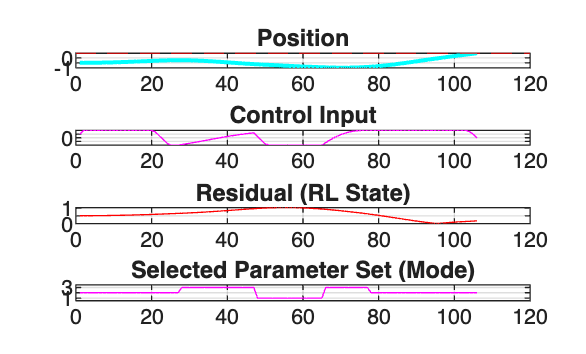

x_true = [-0.5; 0]; x_model = zeros(nx, 1); u_prev = 0; s = 1;
log_y = []; log_u = []; log_r = []; log_mode = [];

for k = 1:400
    [~, a] = max(Q_table(s, :)); % Greedy Policy
    
    % MPC Execution
    current_ref = Modes(a).Ref;
    r_window = current_ref * ones(Np, 1);
    u_base = u_prev * ones(Nc, 1);
    bk = F * x_model + H * u_base;
    fqp = 2 * Phi' * Modes(a).Qbar * (bk - r_window);
    b_u = [u_max*ones(Nc,1)-u_base; -u_min*ones(Nc,1)+u_base];
    [dU, ~, exitflag] = quadprog(Modes(a).Hqp, fqp, [A_du; A_u], [b_du; b_u], [], [], [], [], [], options);
    du = (exitflag>0)*dU(1); u_apply = u_prev + du;
    
    % Physics
    curr_pos = x_true(1); curr_vel = x_true(2);
    new_vel = curr_vel + u_apply*0.0015 - 0.0025*cos(3*curr_pos);
    new_vel = max(min(new_vel, 0.07), -0.07);
    new_pos = curr_pos + new_vel;
    if new_pos<=-1.2, new_pos=-1.2; new_vel=0; end
    if new_pos>=0.6, new_pos=0.6; new_vel=0; end
    x_true = [new_pos; new_vel];
    x_model = A * x_model + B * u_apply;
    
    % Residual
    residual = abs(curr_pos - (C*x_model));
    if residual < res_bins(1), s = 1; elseif residual < res_bins(2), s = 2; else, s = 3; end
    u_prev = u_apply;
    
    log_y = [log_y; curr_pos]; log_u = [log_u; u_apply]; log_r = [log_r; residual]; log_mode = [log_mode; a];
    if curr_pos >= 0.45, break; end
end

figure('Name','RL-MPC Parameter Tuning');
subplot(4,1,1); plot(log_y,'c','LineWidth',1.5); yline(0.45,'r--'); title('Position'); grid on;
subplot(4,1,2); plot(log_u,'m'); title('Control Input'); grid on;
subplot(4,1,3); plot(log_r,'r'); title('Residual (RL State)'); grid on;
subplot(4,1,4); plot(log_mode,'m'); title('Selected Parameter Set (Mode)'); grid on; ylim([0.5 3.5]);


save('data/rl_mpc_results.mat', 'log_y', 'log_u', 'log_r', 'log_mode');
fprintf('Validation Complete.\n');

Validation Complete.


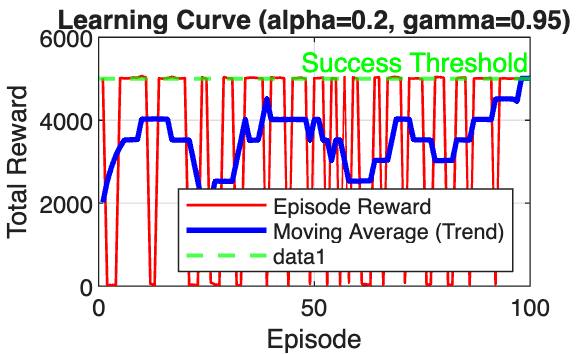



figure('Name', 'RL Training Progress');
plot(1:N_episodes, reward_history, 'Color', 'r', 'LineWidth', 1); hold on;
window_size = 10; 
if N_episodes >= window_size
    moving_avg = movmean(reward_history, window_size);
    plot(1:N_episodes, moving_avg, 'b', 'LineWidth', 2);
    legend('Episode Reward', 'Moving Average (Trend)', 'Location', 'SouthEast');
else
    legend('Episode Reward');
end

xlabel('Episode');
ylabel('Total Reward');
title(['Learning Curve (alpha=' num2str(alpha) ', gamma=' num2str(gamma) ')']);
grid on;
yline(5000, 'g--', 'Success Threshold', 'LineWidth', 1.5);